# 1. a-b

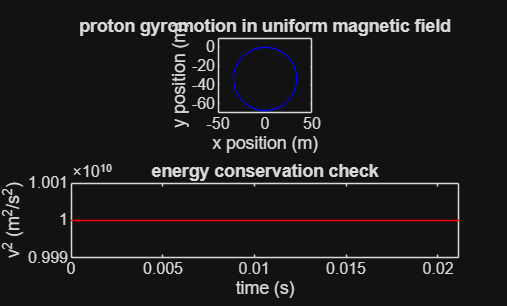


% define physical constants
q = 1.6e-19; % charge of a proton in coulombs
m = 1.67e-27; % mass of proton in kg
bz = 31000e-9; % strength of (Earth's) magnetic field in tesla
v0 = 100000; % initial speed of proton in m/s

omega = (q * bz) / m; % gyrofrequency equation, shows how fast the proton spins
% plugging known values in, omega gives 2,972 rad/sec
% T = 2pi/omega = 0.002 sec, so our time step must be way smaller than this

t_gyro = (2 * pi) / omega; % calculate period of one full gyration/circle

dt = t_gyro / 1000; % time step between each step of RK4 integrator 

n = 10 * 1000; % number of time steps simulation will run for (10 full circles worth of time, 1000 steps per circle)

t = zeros(1, n+1); % creates a row of n + 1 zeros in a row, time axis of simulation
x = zeros(1, n+1); % same thing but store the x position of the proton at every moment in time 
y = zeros(1, n+1); % same but y position
z = zeros(1, n+1); % same but z position
vx = zeros(1, n+1); % stores x component of proton's velocity at every moment
vy = zeros(1, n+1); % same but y component
vz = zeros(1, n+1); % same but z component

% set initial conditions
x(1) = 0; % initial x position
y(1) = 0; % initial y position
z(1) = 0; % initial z position
vx(1) = v0; % initial x velocity
vy(1) = 0; % initial y velocity
vz(1) = 0; % initial z velocity

% RK4 time loop
for i = 1:n
    state = [x(i); y(i); z(i); vx(i); vy(i); vz(i)]; % state vector
    k1 = dt * lorentz(state, q, m, bz); % estimated change in all six quantities in one full time step 
    k2 = dt * lorentz(state + 0.5*k1, q, m, bz); % add half of the estimated change
    k3 = dt * lorentz(state + 0.5*k2, q, m, bz); % add half of the second estimated change
    k4 = dt * lorentz(state + k3, q, m, bz); % estimate change using the full third step
    new_state = state + (1/6) * (k1 + 2*k2 + 2*k3 + k4); % complete updated position and velo one time step later
    % new state = state + 1/6(k1 + 2k2 + 2k3 + k4) from Simpson's rule 

    x(i+1) = new_state(1); % take 1st value out of new_state and store in slot i+1 of the x array
    y(i+1) = new_state(2); % take 2nd value (y) " "
    z(i+1) = new_state(3); 
    vx(i+1) = new_state(4);
    vy(i+1) = new_state(5);
    vz(i+1) = new_state(6);
    t(i+1) = t(i) + dt; % takes current time stored in slot i and adds one dt to it
end

% plot results

% proton gyromotion in uniform mag field (circle)
figure;
subplot(2,1,1); % divides figure window into grid of smaller plot panels (divide figure into 2 rows, divide into 1 col, draw in panel 1)
plot(x, y, 'b-');
axis equal;
axis([-50 50 -70 10]);
xlabel('x position (m)');
ylabel('y position (m)');
title('proton gyromotion in uniform magnetic field');
subplot(2,1,2); % switches focus from the top panel to the bottom panel of figure window


% v^2 over time (should be basically flat)
energy = vx.^2 + vy.^2 + vz.^2; % at every time step i, energy(i) contains: Vx(i)^2+Vy(i)^2+Vz(i)^2, proportional to KE of proton at that moment
plot(t, energy, 'r-');
ylim([9.99e9 1.001e10]);
xlim([0 t(end)]);
xlabel('time (s)');
ylabel('v^2 (m^2/s^2)');
title('energy conservation check'); % energy drop should be basically negligible 

% a perfect simulation would show zero change in v^2 throughout
% any drift indicates numerical error accumulating over time
% smaller drift = more accurate integrator
energy_drift = abs(energy(1) - energy(end)) / energy(1) * 100; 
fprintf('energy drift over 10 gyrations: %.10f%%\n', energy_drift);

energy drift over 10 gyrations: 0.0000000009%



% verify gyroradius
% analytical value comes from r = mV0/qBz derived from Lorentz force equations
% numerical value is the mean distance from the circle center to all points
% percent error or percent drift shows how accurately RK4 reproduced the analytical prediction 
r_analytical = (m * v0) / (q * bz);
x_center = mean(x); % finds center of circle by avg all positions
y_center = mean(y);
r_numerical = mean(sqrt((x - x_center).^2 + (y - y_center).^2)); % d = sqrt[(x2�−x1�)^2+(y2�−y1�)^2]�
fprintf('analytical gyroradius: %.4f meters\n', r_analytical);

analytical gyroradius: 33.6694 meters


fprintf('numerical gyroradius:  %.4f meters\n', r_numerical);

numerical gyroradius:  33.6694 meters


fprintf('percent error: %.6f%%\n', abs(r_analytical - r_numerical)/r_analytical * 100);

percent error: 0.000001%



function dstate = lorentz(state, q, m, bz) % dstate = [dx/dt, dy/dt, dz/dt, dvx/dt, dvy/dt, dvz/dt]
    dstate = zeros(6,1); % output variable to fill w/ derivatives
    vx = state(4);
    vy = state(5);
    vz = state(6);

    dstate(1) = vx; % dx/dt = vx
    dstate(2) = vy; % dy/dt = vy
    dstate(3) = vz; % dz/dt = vz
    dstate(4) = (q/m) * (vy * bz); % dvx/dt = (q/m) * (vy * bz)
    dstate(5) = -(q/m) * (vx * bz); % dvy/dt = -(q/m) * (vx * bz) (the sign changes based on which component of b is 0 due to cross prod)
    dstate(6) = 0; % dvz/dt = 0 (no acceleration in z direction)
end

